# **IO623 - Loopback Test**

This example shows you how to perform a test with the IO623 communication module to verify the send, receive and unpack functionality of two communication controllers (CC).

The IO623 I/O module provides up to four FlexRay controllers (A and B channels) that ensure deterministic transmission with high data rates of 10 Mbit/s per channel and high fault tolerance.

The Simulink model used in this example features the [IO623 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_setup), [IO623 Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_send), [IO623 Receive](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_receive)  and [IO623 Unpack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_unpack) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO623 I/O module with minimum 2 or 4 bus interfaces installed

- Connector cable with 8-pin Binder 712 on one end and 9-pin D-sub connector on the other end

- Cable to connect the two 9-pin D-sub connectors

### Test Setup

The example configures two CCs to communicate with each other. Connect the IO623 I/O module as shown in the diagram below.

From the model, you can see that all the IO623 blocks are triggered by the Interrupt Setup block. For each CC, one Send block transmits a sine wave in the first of four 16-bit words on both channels (A + B). The other words are zero. CC1 transmits on Frame 1; CC2 transmits on Frame 2.

Each output of the Receive block goes to two Unpack blocks, which extract the frame from the other CC on channels A and B respectively. Then, only the first word of the payload is selected to be displayed. The data from channel A is displayed on target scope CC1 and the data from channel B is displayed on target scope CC2.

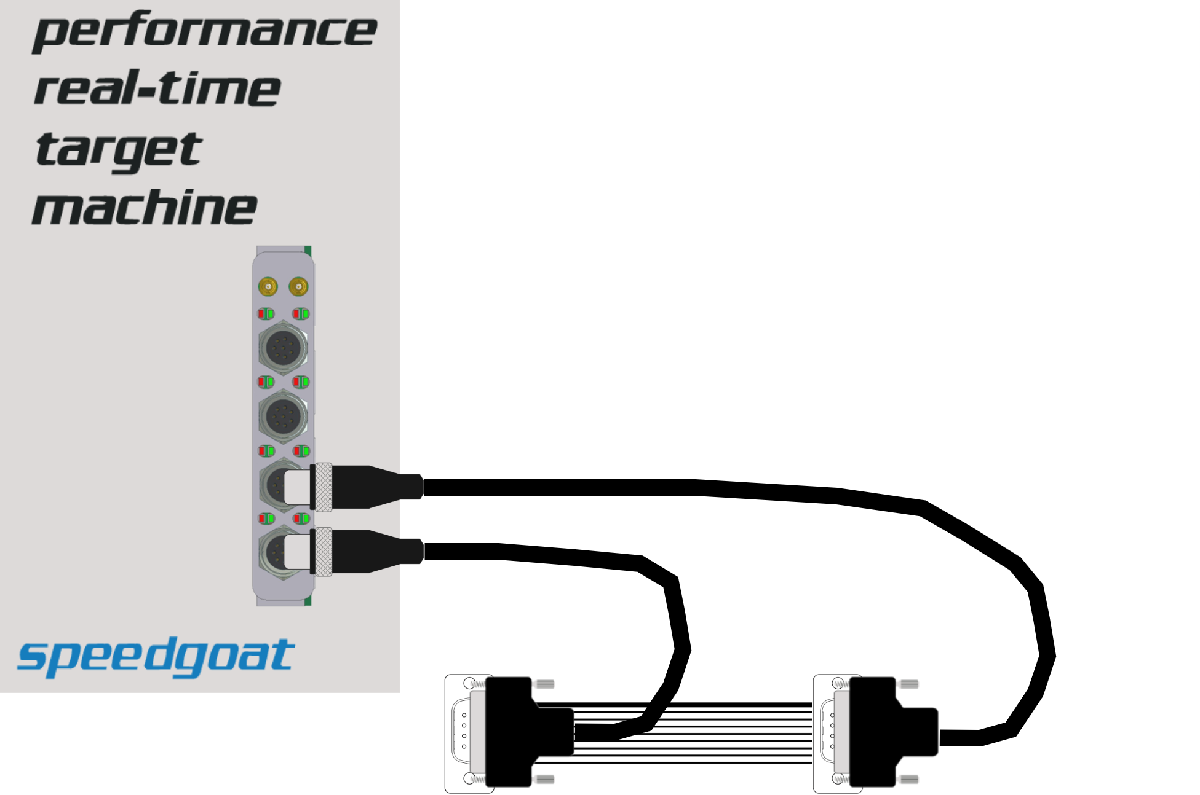

The full pin mapping of the IO623 can be found here: [IO623 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_pin_mapping)

## Open Simulink Model

 
modelName = 'sgMdl_IO623_FlexRayLoopback';
open_system(modelName);         % Open Simulink model

### Model Description

#### Configuration of FlexRay Controller using FIBEX File

A configuration file, namely a CHI File ([IO623 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_setup) block), is required for every CC on your IO623 I/O module. CHI files define all the necessary FlexRay parameters for the CC to connect to (or start up) a FlexRay cluster and send and receive frames. With our CHI Generator Tool (see [IO623 Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_usage_notes)) you can load a FIBEX file, which contains the configuration for a whole FlexRay network, and export the CHI files for the different CCs.

#### Bus Termination

FlexRay buses require termination in the form of a resistor, which sits between the pair of signal wires. Only the end nodes on a multi-drop bus need resistors. Too much or too little resistance can break a FlexRay network. While specific network implementations vary, typical FlexRay networks have a cabling impedance between 80 and 110 Ohms, and the end nodes are terminated to match this impedance. In the [IO623 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_setup) block, the bus termination resistor incorporated with the module can be enabled or disabled per CC.

#### Unpack block: Output ports

The [IO623 Unpack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_unpack) block provides access to the various fields of the received FlexRay frame. To extract these fields from the frame, like the header CRC or the cycle count, check the respective checkbox in the block mask.

#### Unpack block: Data output

The data output port has the same size as the maximum number of 16-bit payload data words, which is 127. For this example the CHI files are configured to a payload data lenght of 4. However, we only use the first word of the payload for the sine wave. A [Selector](https://www.mathworks.com/help/simulink/slref/selector.html) block is therefore used to just select this single word.

## Build, Download, and Run the Example

In this application, the model base rate is determined by an external interrupt signal instead of the CPU timer. The interrupt source is configured in the [Interrupt Setup block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup). For more information, refer to the [IO623 Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_usage_notes).

With every external interrupt, the model will be executed and the execution time will increment by the fundamental sample time. For the execution time to increment correctly (not too fast or too slow), we must manually define the fundamental sample time of the model so that it matches the time between two interrupts: the model does not implicitly know how much time passes between two interrupts.

In this example, the interrupts from the IO623 occur every 2 ms. To apply the fundamental sample time, either run the following code, or in the Simulink model click the **Hardware Settings** button in the **REAL-TIME** tab, click Solver in the left-hand pane, then enter 0.002 in the **Fixed-step size (fundamental sample time)** field under **Solver details**.

 
% Change model step size
set_param('sgMdl_IO623_FlexRayLoopback', 'SolverName', 'FixedStepDiscrete');
set_param('sgMdl_IO623_FlexRayLoopback', 'FixedStep', '0.002');

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

Open the Simulink scope connected to the [IO623 Unpack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io623_unpack) blocks and check if the signals displayed correspond to the signals below. Two signals must be displayed per scope. The screenshots below provide examples of two sine wave signals.

  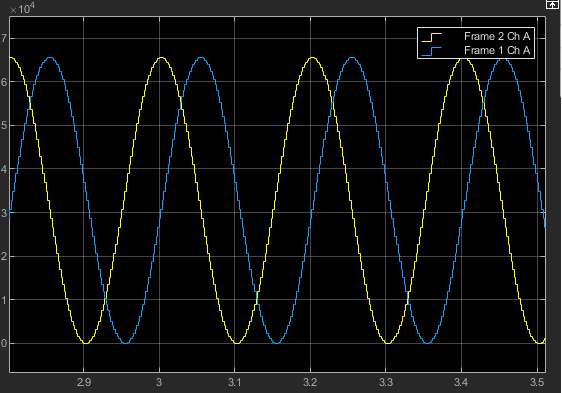

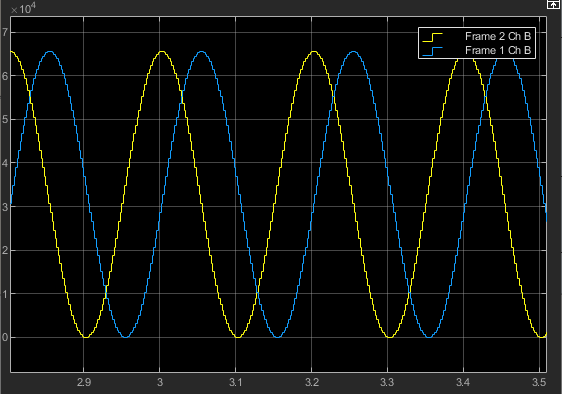

## Additional References

- [IO623 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io623)